# EDB Power Electronics SS2023

## Seminar 01 -- magentics

### Design goals

clear; clc;

L               = 330e-6;   %H
Imax            = 2.4;      %A
Bmax            = 200e-3;   %T
Fcu             = 0.5;
Rcu             = 100e-3;   %Ohm


mu0 = 0.4*pi*1e-6;          %Vs/Am
mur = 2900;
rhoCu = 0.01786e-6;         %Ohm m

### Core Selection

using the KG method and Excel Sheet in ILIAS

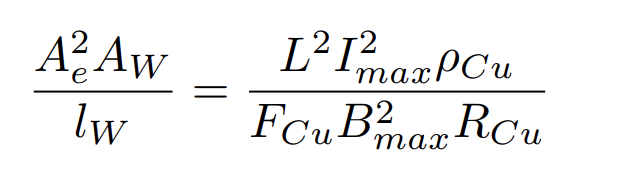

KG_required = L^2 * Imax^2 * rhoCu / (Fcu * Bmax^2 * Rcu)

KG_required = 5.6015e-12

The datesheets show that the PQ26/20 is suitable.

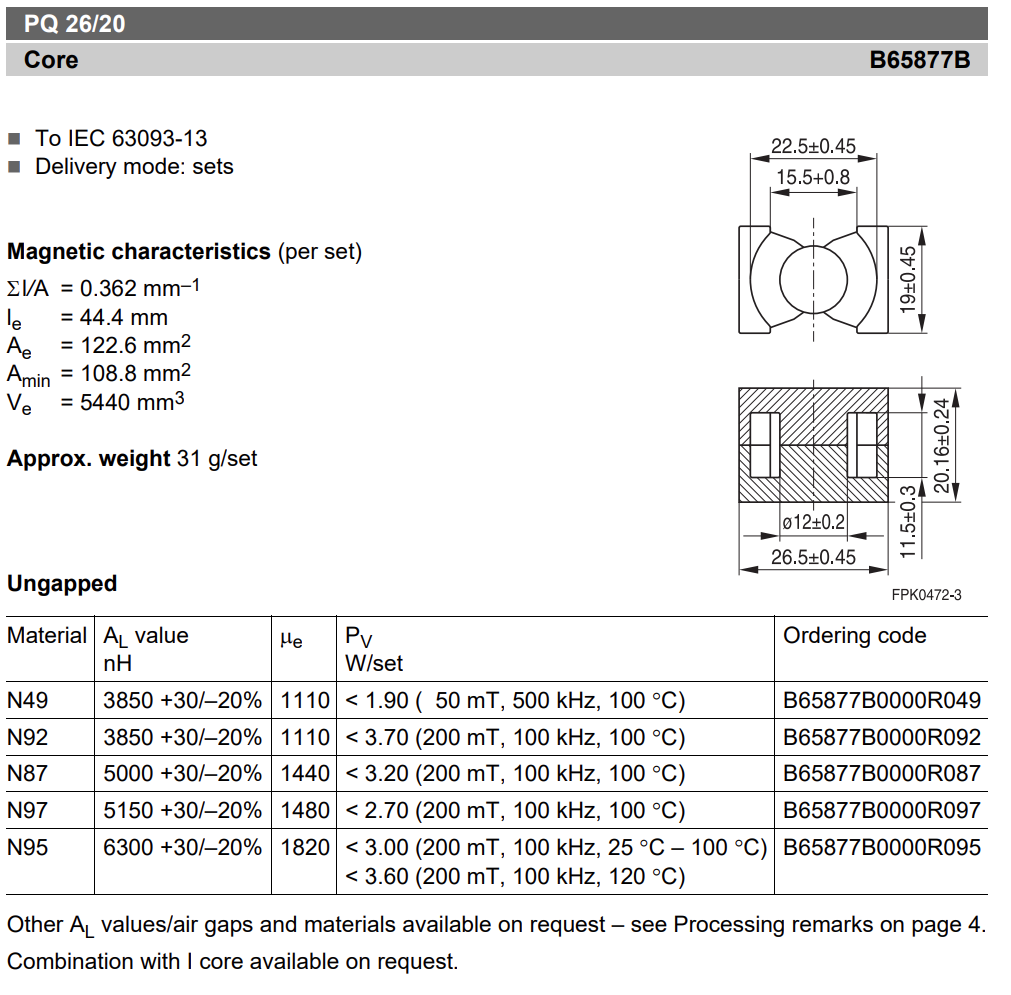

%PQ26/60 Data
lfe                 = 44.4e-3;  %m
Afe                 = 122.6e-6; %m²
Aw                  = 33e-6;    %m²
lw                  = 56e-3;    %m

## Number of turns

Nfloat = (L * Imax) / (Bmax *Afe)

Nfloat = 32.3002

N = ceil(Nfloat)

N = 33

Check L without air gap

L_ungapped = N^2 * mu0 * mur * Afe/lfe

L_ungapped = 0.0110

Rm = Rm_Fe + Rm_L -> series magnetic circuit

## Dimension the air gap

assumed with no air gap widening -> Aair = Afe


$$R_{m,air} = \frac{l_{air}}{\mu_{0} \cdot \mu_{r} \cdot A_{air} }$$


 with µr = 1

Rm_Fe = lfe / (mu0 * mur * Afe)

Rm_Fe = 9.9377e+04


Aair = Afe

Aair = 1.2260e-04


Rm_Air = N^2/L - Rm_Fe

Rm_Air = 3.2006e+06


lair = Rm_Air * mu0 * 1 * Aair

lair = 4.9310e-04


disp(['The required air gap is ' num2str(lair * 1e3) ' mm'])

The required air gap is 0.4931 mm


## Check the DC resistance

Acu = (Aw * Fcu) / N

Acu = 5.0000e-07


lcu = lw * N

lcu = 1.8480

Rcu_check = rhoCu * lcu / Acu

Rcu_check = 0.0660

## Check that Bmax is not violated at Imax


$$\Phi_{max} = \frac{1}{R_{m,total}} \cdot N \cdot  I_{max}$$



$$B_{max} = \frac{\Phi_{max}}{A_{Fe}}$$


RmTotal = Rm_Air + Rm_Fe;
PhiMax = 1 / (Rm_Air + Rm_Fe) * N * Imax;
Bmax_check = PhiMax / Afe 

Bmax_check = 0.1958

## Check L gapped

L_gapped = N^2 * 1/RmTotal

L_gapped = 3.3000e-04